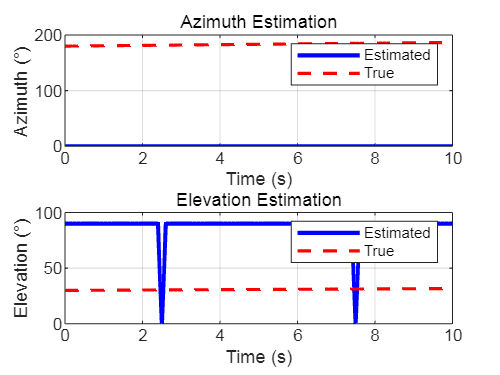

% Radar Toolbox Implementation with Rotating Linear Array

% 参数设置
c = physconst('LightSpeed'); % 光速
f = 5e8;                    % 雷达频率 (500 MHz)
lambda = c / f;             % 波长计算
d = lambda / 2;             % 阵元间距 (半波长)
num_elements = 5;           % 线阵阵元数

% 线阵初始位置（沿x轴，中心对称）
x_initial = linspace(-(num_elements-1)*d/2, (num_elements-1)*d/2, num_elements);
y_initial = zeros(1, num_elements);
z_initial = zeros(1, num_elements);

% 仿真参数
simulation_time = 10;        % 仿真时间 (秒)
time_step = 0.1;             % 时间步长 (秒)
time = 0:time_step:simulation_time;
num_steps = length(time);

% 线阵旋转角度（随时间线性增加）
rotation_angle = linspace(0, 360, num_steps); % 单位：度

% 目标参数（方位角和仰角动态变化）
theta_target = 60 * sind(2*pi*0.1*time) + 180; % 方位角
phi_target = 30 * sind(2*pi*0.05*time) + 30;  % 仰角

% 扫描参数
theta_scan = 0:2:360;       % 方位角扫描范围
phi_scan = 0:2:90;          % 仰角扫描范围
[THETA, PHI] = meshgrid(theta_scan, phi_scan);

% 初始化存储变量
detected_theta = zeros(1, num_steps);
detected_phi = zeros(1, num_steps);

% 波数
k = 2*pi/lambda;

% 主循环
for t = 1:num_steps
    % 当前旋转角度
    phi_rot = rotation_angle(t);
    
    % 计算旋转后的阵元位置
    x_rot = x_initial*cosd(phi_rot) - y_initial*sind(phi_rot);
    y_rot = x_initial*sind(phi_rot) + y_initial*cosd(phi_rot);
    z_rot = z_initial;
    
    % 计算阵列响应
    response = zeros(size(THETA));
    for i = 1:length(theta_scan)
        for j = 1:length(phi_scan)
            % 波达方向单位矢量
            u = [cosd(THETA(j,i))*cosd(PHI(j,i)); 
                 sind(THETA(j,i))*cosd(PHI(j,i));
                 sind(PHI(j,i))];
            
            % 计算相位差
            phase = k * (u' * [x_rot; y_rot; z_rot]);
            
            % 阵列响应
            response(j,i) = abs(sum(exp(1i*phase)));
        end
    end
    
    % 归一化响应
    response = response / max(response(:));
    
    % 检测峰值
    [max_val, idx] = max(response(:));
    [row, col] = ind2sub(size(response), idx);
    detected_theta(t) = THETA(row, col);
    detected_phi(t) = PHI(row, col);
end

% 结果可视化
figure;
subplot(2,1,1);
plot(time, detected_theta, 'b', 'LineWidth', 2);
hold on;
plot(time, theta_target, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Azimuth (°)');
legend('Estimated', 'True');
title('Azimuth Estimation');
grid on;

subplot(2,1,2);
plot(time, detected_phi, 'b', 'LineWidth', 2);
hold on;
plot(time, phi_target, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Elevation (°)');
legend('Estimated', 'True');
title('Elevation Estimation');
grid on;